%
% Copyright (c) 2015, Mostapha Kalami Heris & Yarpiz (www.yarpiz.com)
% All rights reserved. Please read the "LICENSE" file for license terms.
%
% Project Code: YPEA120
% Project Title: Non-dominated Sorting Genetic Algorithm II (NSGA-II)
% Publisher: Yarpiz (www.yarpiz.com)
% 
% Developer: Mostapha Kalami Heris (Member of Yarpiz Team)
% 
% Cite as:
% Mostapha Kalami Heris, NSGA-II in MATLAB (URL: https://yarpiz.com/56/ypea120-nsga2), Yarpiz, 2015.
% 
% Contact Info: sm.kalami@gmail.com, info@yarpiz.com
%

clc;
clear;
close all;

## Problem Definition

%CostFunction = @(x) MOP4(x);      % Cost Function

%nVar = 4;             % Number of Decision Variables

%VarSize = [1 nVar];   % Size of Decision Variables Matrix

%VarMin = -5;          % Lower Bound of Variables
%VarMax = 5;          % Upper Bound of Variables

% Number of Objective Functions
%nObj = numel(CostFunction(unifrnd(VarMin, VarMax, VarSize)));

## NSGA-II Parameters

MaxIt = 50;      % Maximum Number of Iterations

nPop = 200;        % Population Size

pCrossover = 0.5;                         % Crossover Percentage
nCrossover = 2*round(pCrossover*nPop/2);  % Number of Parnets (Offsprings)

pMutation = 0.1;                          % Mutation Percentage
nMutation = round(pMutation*nPop);        % Number of Mutants

mu = 0.02;                    % Mutation Rate

%sigma = 0.1*(VarMax-VarMin);  % Mutation Step Size
sigma = 0.1;

D_ft = 0.280343447; %Important Parameter


range.D_sw   = [(0.2*D_ft),(0.3 .* D_ft)];
range.L_pz   = [(2.*D_ft/3) , (3.*D_ft/4)];
range.fi_pz  = [1 , 1.4];
range.TQ     = [0.2 , 0.85];

## Initialization

empty_individual.Position = [];
empty_individual.Cost = [];
empty_individual.Rank = [];
empty_individual.DominationSet = [];
empty_individual.DominatedCount = [];
empty_individual.CrowdingDistance = [];

pop = repmat(empty_individual, nPop, 1);

variables = Creat_Population(nPop,D_ft,range);

for i = 1:nPop
    
    pop(i).Position = variables(i,:);
    
    pop(i).Cost = Eval(pop(i).Position);
    
end

% Non-Dominated Sorting
[pop, F] = NonDominatedSorting(pop);

% Calculate Crowding Distance
pop = CalcCrowdingDistance(pop, F);

% Sort Population
[pop, F] = SortPopulation(pop);

## NSGA-II Main Loop

Iteration 1: Number of F1 Members = 13
Iteration 2: Number of F1 Members = 13
Iteration 3: Number of F1 Members = 13
Iteration 4: Number of F1 Members = 15
Iteration 5: Number of F1 Members = 17
Iteration 6: Number of F1 Members = 17
Iteration 7: Number of F1 Members = 11
Iteration 8: Number of F1 Members = 10
Iteration 9: Number of F1 Members = 11
Iteration 10: Number of F1 Members = 10
Iteration 11: Number of F1 Members = 15
Iteration 12: Number of F1 Members = 14
Iteration 13: Number of F1 Members = 16
Iteration 14: Number of F1 Members = 17
Iteration 15: Number of F1 Members = 15
Iteration 16: Number of F1 Members = 16
Iteration 17: Number of F1 Members = 19
Iteration 18: Number of F1 Members = 21
Iteration 19: Number of F1 Members = 21
Iteration 20: Number of F1 Members = 22
Iteration 21: Number of F1 Members = 21
Iteration 22: Number of F1 Members = 19
Iteration 23: Number of F1 Members = 21
Iteration 24: Number of F1 Members = 24
Iteration 25: Number of F1 Members = 29
Iteration

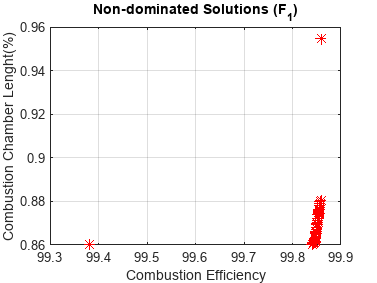

for it = 1:MaxIt
    % Crossover
    popc = repmat(empty_individual, nCrossover/2, 2);
    for k = 1:nCrossover/2
        
        i1 = randi([1 nPop]);
        p1 = pop(i1);
        
        i2 = randi([1 nPop]);
        p2 = pop(i2);
        
        [popc(k, 1).Position, popc(k, 2).Position] = Crossover(p1.Position, p2.Position);
        
        popc(k, 1).Cost = Eval(popc(k, 1).Position);
        popc(k, 2).Cost = Eval(popc(k, 2).Position);
        
    end
    popc = popc(:);
    
    % Mutation
    popm = repmat(empty_individual, nMutation, 1);
    for k = 1:nMutation
        
        i = randi([1 nPop]);
        p = pop(i);
        
        popm(k).Position = Mutate(p.Position, mu, sigma,range);
        
        popm(k).Cost = Eval(popm(k).Position);
        
    end
    
    % Merge
    pop = [pop
         popc
         popm]; %#ok
     
    % Non-Dominated Sorting
    [pop, F] = NonDominatedSorting(pop);

    % Calculate Crowding Distance
    pop = CalcCrowdingDistance(pop, F);

    % Sort Population
    pop = SortPopulation(pop);
    
    % Truncate
    pop = pop(1:nPop);
    
    % Non-Dominated Sorting
    [pop, F] = NonDominatedSorting(pop);

    % Calculate Crowding Distance
    pop = CalcCrowdingDistance(pop, F);

    % Sort Population
    [pop, F] = SortPopulation(pop);
    
    % Store F1
    F1 = pop(F{1});
    
    % Show Iteration Information
    disp(['Iteration ' num2str(it) ': Number of F1 Members = ' num2str(numel(F1))]);
    
    % Plot F1 Costs
    figure(1);
    PlotCosts(F1);
    pause(0.01);
    
end

## Results